# Question 3

## Part 1

Using the code provided as part of the assignment, create SIFT features in two consecutive images.

Using images 1 and 2 in the horizontal sequence.

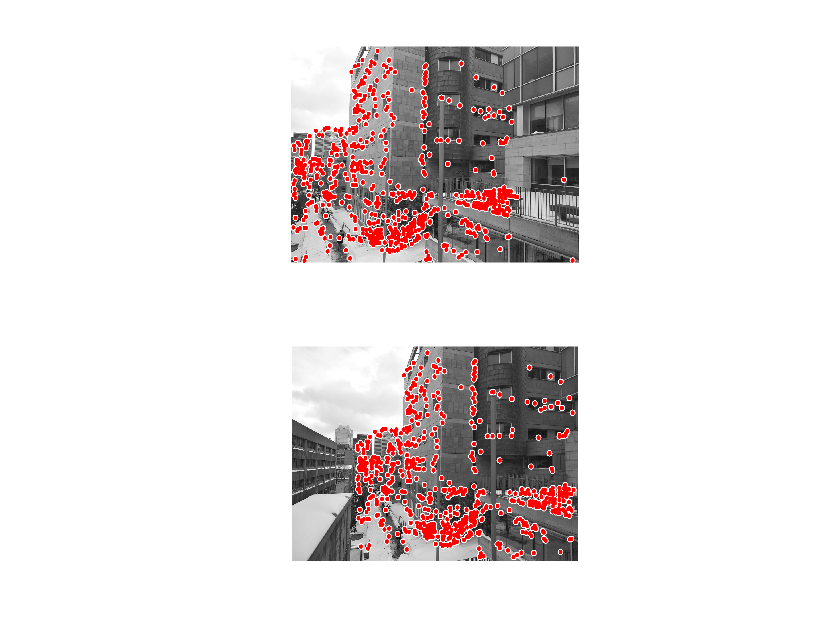

I1 = imread("q3datasets/horizontal/1.png"); %first image
I2 = imread("q3datasets/horizontal/2.png"); %second image

I1 = rgb2gray(I1);
I2 = rgb2gray(I2);

%returns a SIFTPoints object, points, containing information about SIFT features detected in the 2-D grayscale input image I. 
ptsLeft  = detectSIFTFeatures(I1); 
ptsRight = detectSIFTFeatures(I2);

%ExtractFeatures: Returns [features, validPoints], extracted feature vectors, also known as
%descriptors, and their corresponding locations.
[featuresLeft,  validPtsLeft]  = extractFeatures(I1,  ptsLeft);
[featuresRight, validPtsRight] = extractFeatures(I2, ptsRight);

%indexPairs the matching feature vectors and return the matching points
%index in featuresLeft, and featuresRight
indexPairs = matchFeatures(featuresLeft, featuresRight);

%Get the valid points using the index.
matchedLeft  = validPtsLeft(indexPairs(:,1));
matchedRight = validPtsRight(indexPairs(:,2));

% display matched attributes
clf reset;
subplot(2, 1, 1)
imshow(I1)
hold on
viscircles(matchedLeft.Location, 1*ones([1 length(matchedLeft.Location)]));
hold off
subplot(2,1,2)
imshow(I2)
hold on
viscircles(matchedRight.Location, 1*ones([1 length(matchedLeft.Location)]));
hold off

The red dots correspond to matched features between these successive images.

Now try the same with images 1 and 2 of the vertical sequence.

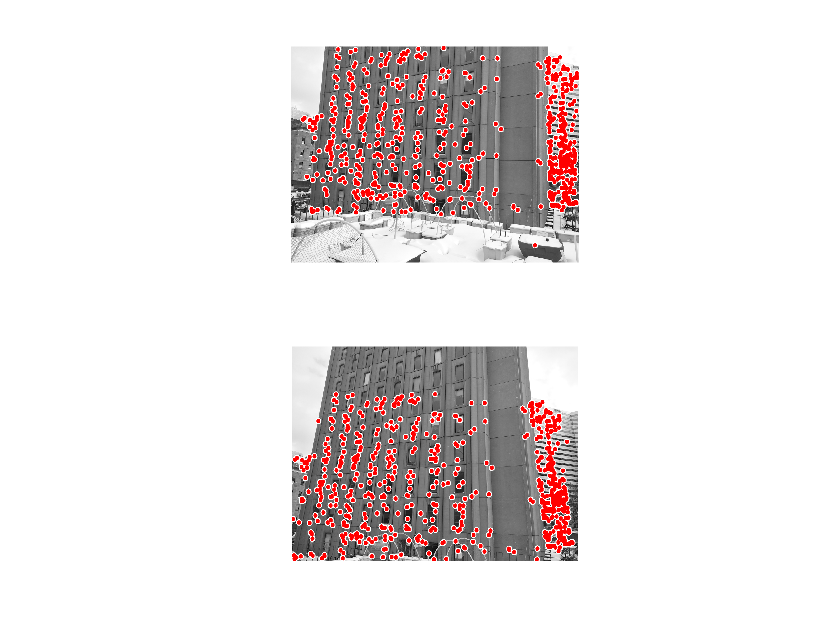

I1 = imread("q3datasets/vertical/1.png"); %first image
I2 = imread("q3datasets/vertical/2.png"); %second image

I1 = rgb2gray(I1);
I2 = rgb2gray(I2);

%returns a SIFTPoints object, points, containing information about SIFT features detected in the 2-D grayscale input image I. 
ptsLeft  = detectSIFTFeatures(I1); 
ptsRight = detectSIFTFeatures(I2);

%ExtractFeatures: Returns [features, validPoints], extracted feature vectors, also known as
%descriptors, and their corresponding locations.
[featuresLeft,  validPtsLeft]  = extractFeatures(I1,  ptsLeft);
[featuresRight, validPtsRight] = extractFeatures(I2, ptsRight);

%indexPairs the matching feature vectors and return the matching points
%index in featuresLeft, and featuresRight
indexPairs = matchFeatures(featuresLeft, featuresRight);

%Get the valid points using the index.
matchedLeft  = validPtsLeft(indexPairs(:,1));
matchedRight = validPtsRight(indexPairs(:,2));

% display matched attributes
clf reset;
subplot(2, 1, 1)
imshow(I1)
hold on
viscircles(matchedLeft.Location, 1*ones([1 length(matchedLeft.Location)]));
hold off
subplot(2,1,2)
imshow(I2)
hold on
viscircles(matchedRight.Location, 1*ones([1 length(matchedLeft.Location)]));
hold off

The red dots correspond to matched features between these successive images.

## Part 3 (RANSAC)

The idea of RANSAC is to choose the minimal number of matching samples in computing the model in order to minimize the chances of picking outlying points. The algorithm proceeds as follows:

1) Find multiple SIFT feature points in both images. For each feature point in an image, find a set of candidate feature points which correspond to it in the other image. We get a 4-tuple (xi, yi, xi', yi').

2) From this set of 4-tuples, randomly select four of them and fit an exact homography which maps (xi, yi) to (xi', yi') exactly, using the equations seen in class (assuming the translational component is 0 and we only have a rotation). Find the consensus set (set of points very close to (xi', yi')). Distance can be defined as the 2-norm between the points. If the consensus set is really large, save the current homography as the best so far in order to save the current model.

3) Repeat step 2 for a certain number of iterations, or until we obtain a homography whose magnitude of the consensus set exceeds a certain threshold.

Implement algorithm.

Useful figures for calculations done within the algorithm:

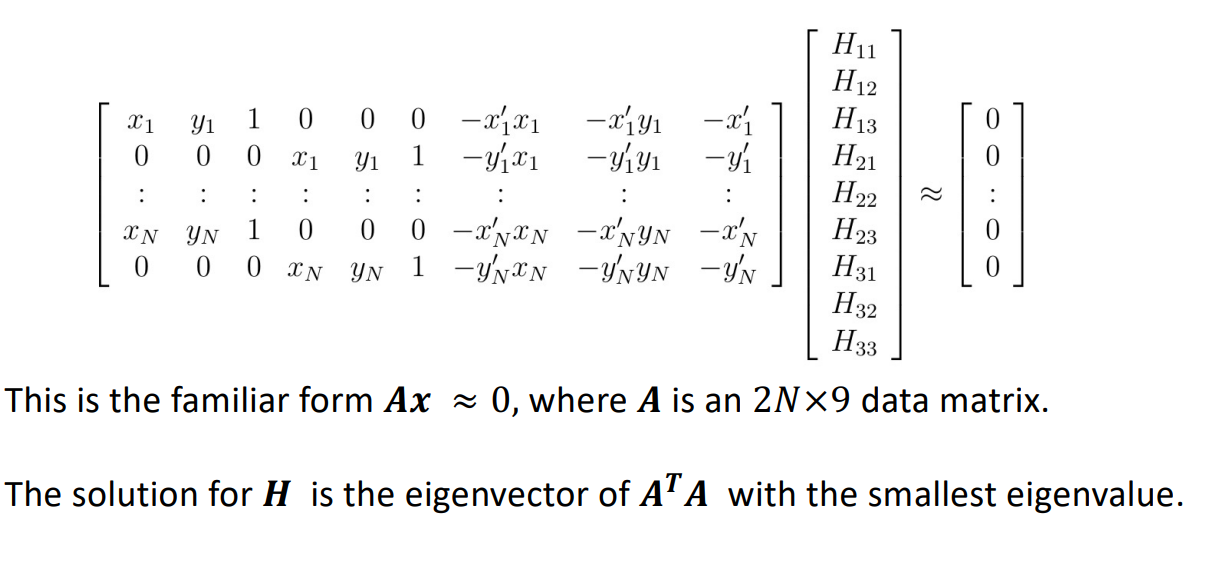

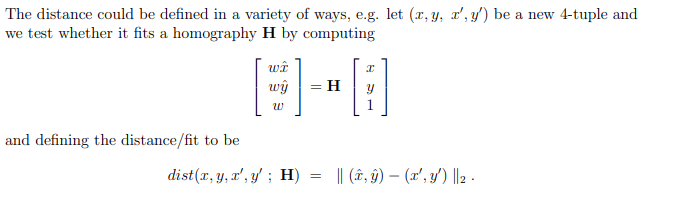

N = 100; % number of iterations for RANSAC
distance_threshold = 10; % what is considered a good distance between points

% step 1: already obtained features from part 1)

% step 2: randomly sample 4 pairs of feature points from both images
features_count = matchedLeft.Count;

best_consesus_set_size = 0;
best_homography = zeros([3 3]);

for k=1:N
    random_index_1 = randi([1 features_count], 1, 1);
    random_index_2 = randi([1 features_count], 1, 1);
    random_index_3 = randi([1 features_count], 1, 1);
    random_index_4 = randi([1 features_count], 1, 1);
    % fetch corresponding (xi,yi) and (xi',yi')
    x1 = floor(matchedLeft.Location(random_index_1, 1));
    x2 = floor(matchedLeft.Location(random_index_2, 1));
    x3 = floor(matchedLeft.Location(random_index_3, 1));
    x4 = floor(matchedLeft.Location(random_index_4, 1));
    y1 = floor(matchedLeft.Location(random_index_1, 2));
    y2 = floor(matchedLeft.Location(random_index_2, 2));
    y3 = floor(matchedLeft.Location(random_index_3, 2));
    y4 = floor(matchedLeft.Location(random_index_4, 2));
    x1_prime = floor(matchedRight.Location(random_index_1, 1));
    x2_prime = floor(matchedRight.Location(random_index_2, 1));
    x3_prime = floor(matchedRight.Location(random_index_3, 1));
    x4_prime = floor(matchedRight.Location(random_index_4, 1));
    y1_prime = floor(matchedRight.Location(random_index_1, 2));
    y2_prime = floor(matchedRight.Location(random_index_2, 2));
    y3_prime = floor(matchedRight.Location(random_index_3, 2));
    y4_prime = floor(matchedRight.Location(random_index_4, 2));
    
    % set up A matrix
    A = zeros([8 9]);
    A(1,1) = x1;
    A(1,2) = y1;
    A(1,3) = 1;
    A(1,7) = -1*x1_prime*x1;
    A(1,8) = -1*x1_prime*y1;
    A(1,9) = -1*x1_prime;
    
    A(2,4) = x1;
    A(2,5) = y1;
    A(2,6) = 1;
    A(2,7) = -1*y1_prime*x1;
    A(2,8) = -1*y1_prime*y1;
    A(2,9) = -1*y1_prime;
    
    A(3,1) = x2;
    A(3,2) = y2;
    A(3,3) = 1;
    A(3,7) = -1*x2_prime*x2;
    A(3,8) = -1*x2_prime*y2;
    A(3,9) = -1*x2_prime;
    
    A(4,4) = x2;
    A(4,5) = y2;
    A(4,6) = 1;
    A(4,7) = -1*y2_prime*x2;
    A(4,8) = -1*y2_prime*y2;
    A(4,9) = -1*y2_prime;
    
    A(5,1) = x3;
    A(5,2) = y3;
    A(5,3) = 1;
    A(5,7) = -1*x3_prime*x3;
    A(5,8) = -1*x3_prime*y3;
    A(5,9) = -1*x3_prime;
    
    A(6,4) = x3;
    A(6,5) = y3;
    A(6,6) = 1;
    A(6,7) = -1*y3_prime*x3;
    A(6,8) = -1*y3_prime*y3;
    A(6,9) = -1*y3_prime;
    
    A(7,1) = x4;
    A(7,2) = y4;
    A(7,3) = 1;
    A(7,7) = -1*x4_prime*x4;
    A(7,8) = -1*x4_prime*y4;
    A(7,9) = -1*x4_prime;
    
    A(8,4) = x4;
    A(8,5) = y4;
    A(8,6) = 1;
    A(8,7) = -1*y4_prime*x4;
    A(8,8) = -1*y4_prime*y4;
    A(8,9) = -1*y4_prime;
    
    % obtain SVD decomposition of A
    [U, S, V] = svd(A);
    % find column vector of V corresponding to a singular value of 0
    column_number = -1;
    for i=1:8
        if floor(S(i,i)) == 0
            column_number = i;
            break;
        end
    end
    
    if column_number == -1
        continue
    end

    % retrieve the H vector
    H_vector = V(:, column_number);
    % form the H matrix
    H = zeros([3 3]);
    H(1,1) = H_vector(1,1);
    H(1,2) = H_vector(2,1);
    H(1,3) = H_vector(3,1);
    H(2,1) = H_vector(4,1);
    H(2,2) = H_vector(5,1);
    H(2,3) = H_vector(6,1);
    H(3,1) = H_vector(7,1);
    H(3,2) = H_vector(8,1);
    H(3,3) = H_vector(9,1);
    % get feature locations obtained by applying the homography on the
    % feature locations of the left image, and see if they are close enough to
    % (xi',yi')
    current_consensus_set_size = 0;
    
    for i=1:features_count
        x_current_left = floor(matchedLeft.Location(i, 1));
        y_current_left = floor(matchedLeft.Location(i, 2));
    
        % retrieve true matches from right image
        x_true_right = floor(matchedRight.Location(i, 1));
        y_true_right = floor(matchedRight.Location(i, 2));
    
        % compute result of homography on matches in left image
        vector = H * [x_current_left; y_current_left; 1];
        vector = round(vector / vector(3, 1)); % divide by w and round
        x_hat = vector(1,1);
        y_hat = vector(2,1);
    
        % compute distance between true matches and matches under the
        % homography
        distance = sqrt((x_true_right - x_hat)^2 + (y_true_right - y_hat)^2);
        if distance < distance_threshold
            current_consensus_set_size = current_consensus_set_size + 1;
        end
    
    end
    
    % update best homography model
    if current_consensus_set_size >= best_consesus_set_size
        best_consesus_set_size = current_consensus_set_size;
        best_homography = H;
    end

end

best_homography

best_homography =    -0.0063    0.0006    0.1233
   -0.0001   -0.0055   -0.9923
   -0.0000    0.0000   -0.0062


Here, we have a homography which we think is a good model, with 100 iterations of RANSAC and a distance threshold of 10 pixels. Apply the homography on the features found in the left image in order to obtain features in the right image, and illustrate those features in both images.

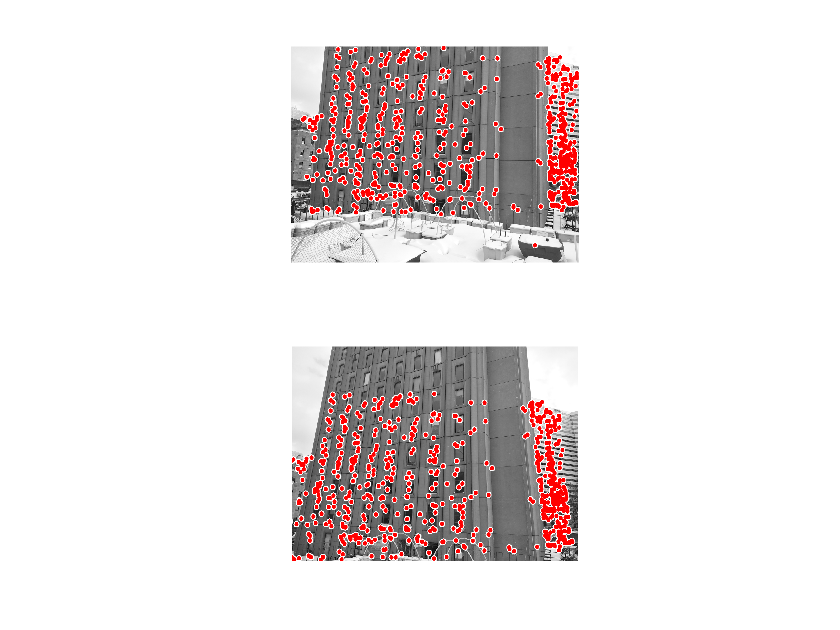

matched_locations = zeros([features_count 2]);

for i=1:features_count
    x_current_left = floor(matchedLeft.Location(i, 1));
    y_current_left = floor(matchedLeft.Location(i, 2));
    vector = best_homography * [x_current_left; y_current_left; 1];
    vector = round(vector / vector(3, 1)); % divide by w and round
    x_hat = vector(1,1);
    y_hat = vector(2,1);
    
    matched_locations(i, :) = [x_hat y_hat];
    
    
end

% display matched attributes
clf reset;
subplot(2, 1, 1)
imshow(I1)
hold on
viscircles(matchedLeft.Location, 1*ones([1 length(matchedLeft.Location)]));
hold off
subplot(2,1,2)
imshow(I2)
hold on
viscircles(matched_locations, 1*ones([1 length(matched_locations)]));
hold off

Now stitch those images together.

Process:

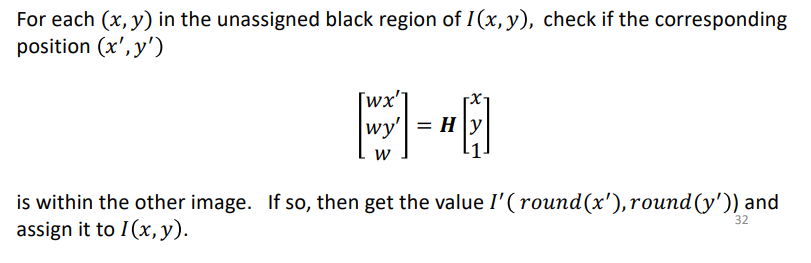

First place the left image in a larger black canvas.

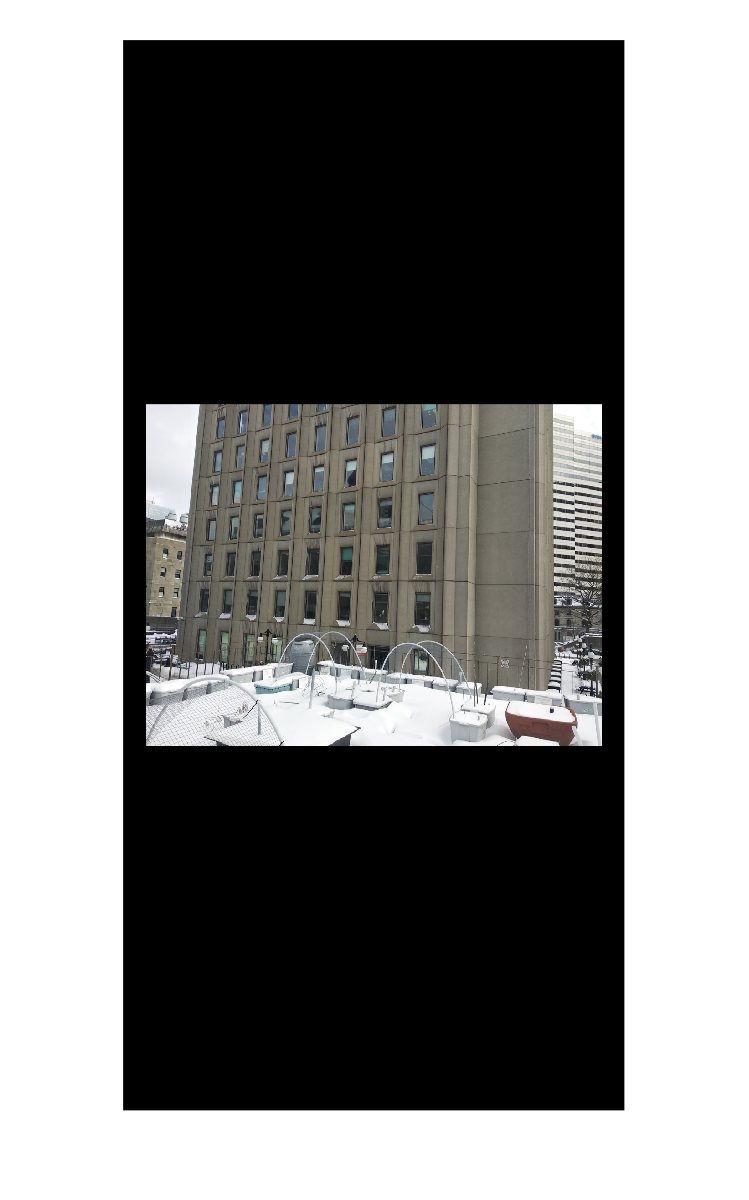

original_I1 = imread("q3datasets/vertical/1.png");
original_I2 = imread("q3datasets/vertical/2.png");

[height, width] = size(I1);
canvas = padarray(original_I1, [800 50], 'both');

clf reset;
imshow(canvas)

Go through each pixel in the canvas, obtain the corresponding location in the right image through the homography, and if it's a valid pixel, colour it in.

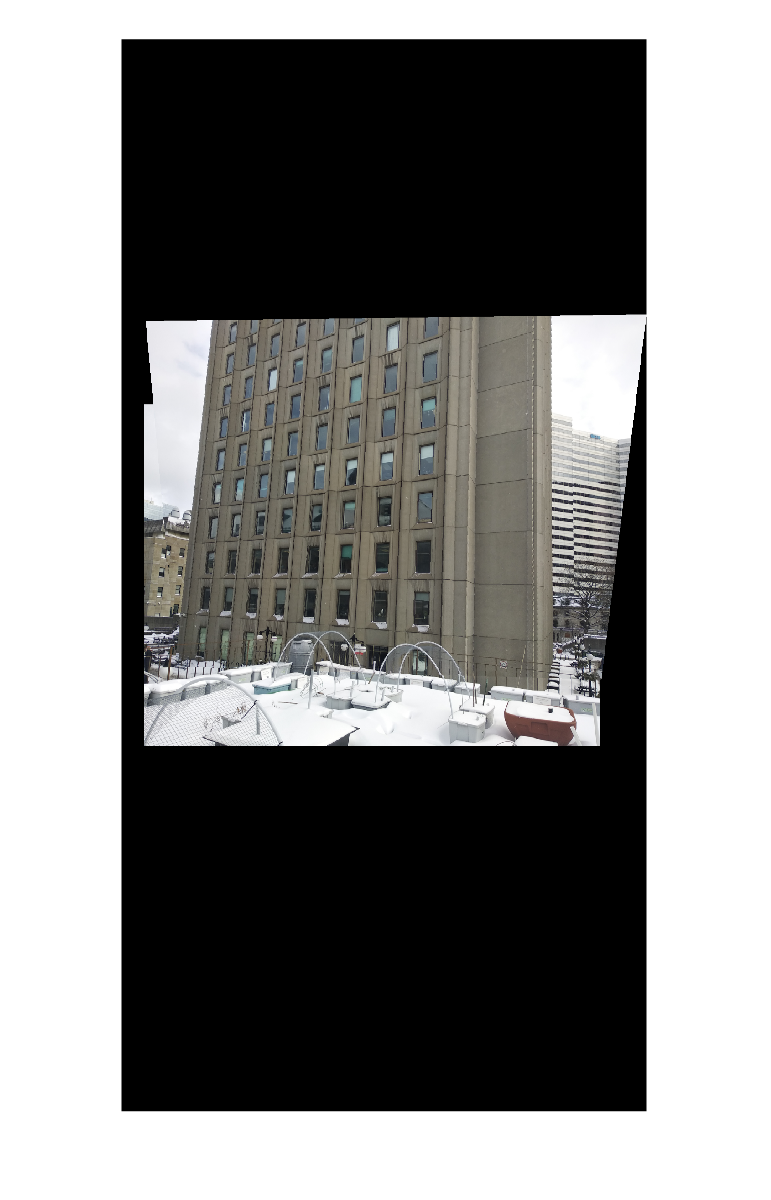

[canvas_height, canvas_width] = size(canvas);

for x=1:canvas_width
    for y=1:canvas_height
        
        % the origin corresponds to the top-left of the original image
        % therefore x will be x - 50
        % and y will be y - 800 (these are the padding sizes)
        x_canvas = x - 50;
        y_canvas = y - 800;

        % get location in right image through homography
        vector = best_homography * [x_canvas; y_canvas; 1];
        vector = round(vector / vector(3, 1)); % divide by w and round
        x_hat = vector(1,1);
        y_hat = vector(2,1);

        % get RGB only if it's a valid pixel
        if x_hat >= 1 && x_hat <= width && y_hat >= 1 && y_hat <= height
            pixel = original_I2(y_hat, x_hat, :);
            % color corresponding slot
            canvas(y, x, :) = pixel;
        end
        
    end
end

clf reset;
imshow(canvas)

## Part 5

Repeat the same process on the following sequential pictures I've taken of my home office.

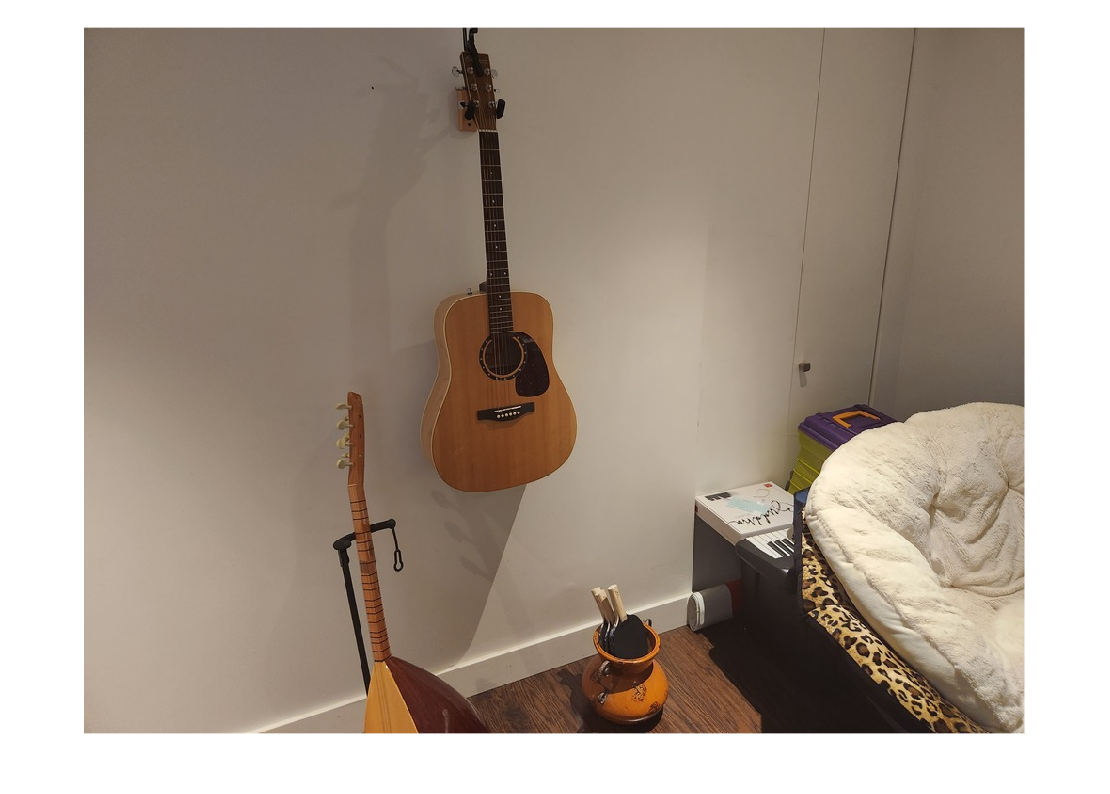

I1 = imread("q3_part5_img1.jpg"); %first image
I2 = imread("q3_part5_img2.jpg"); %second image
imshow(I1);

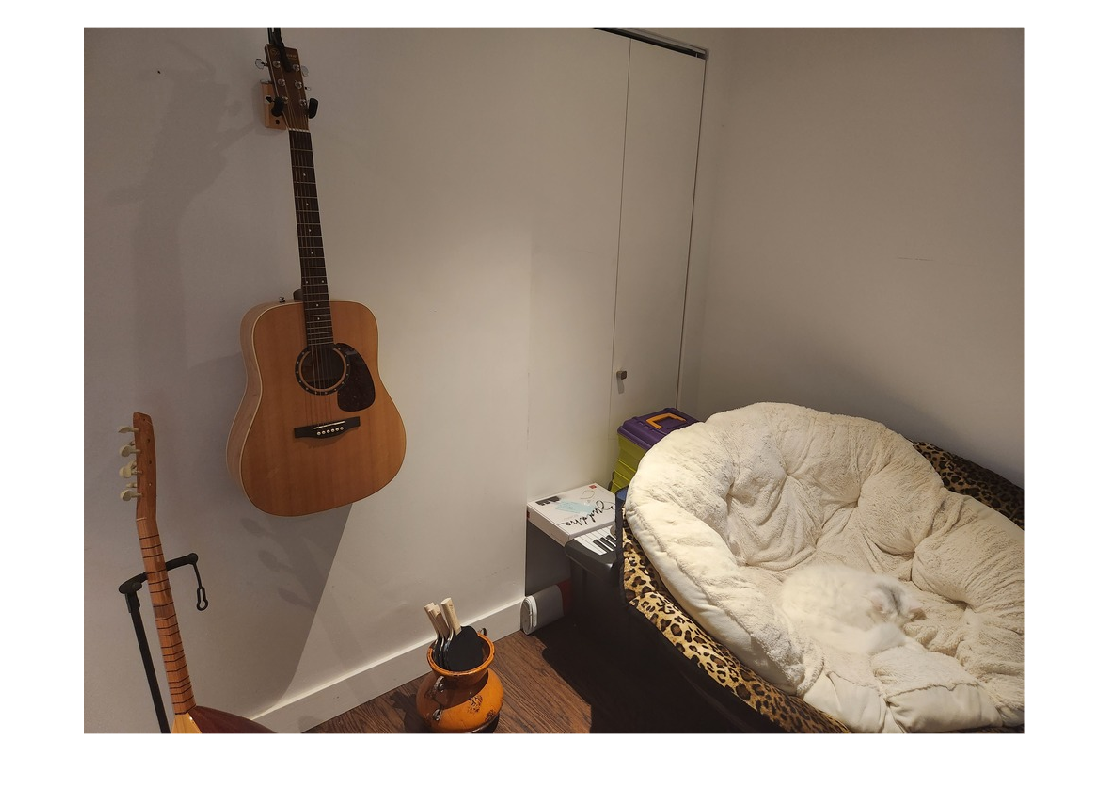

imshow(I2);

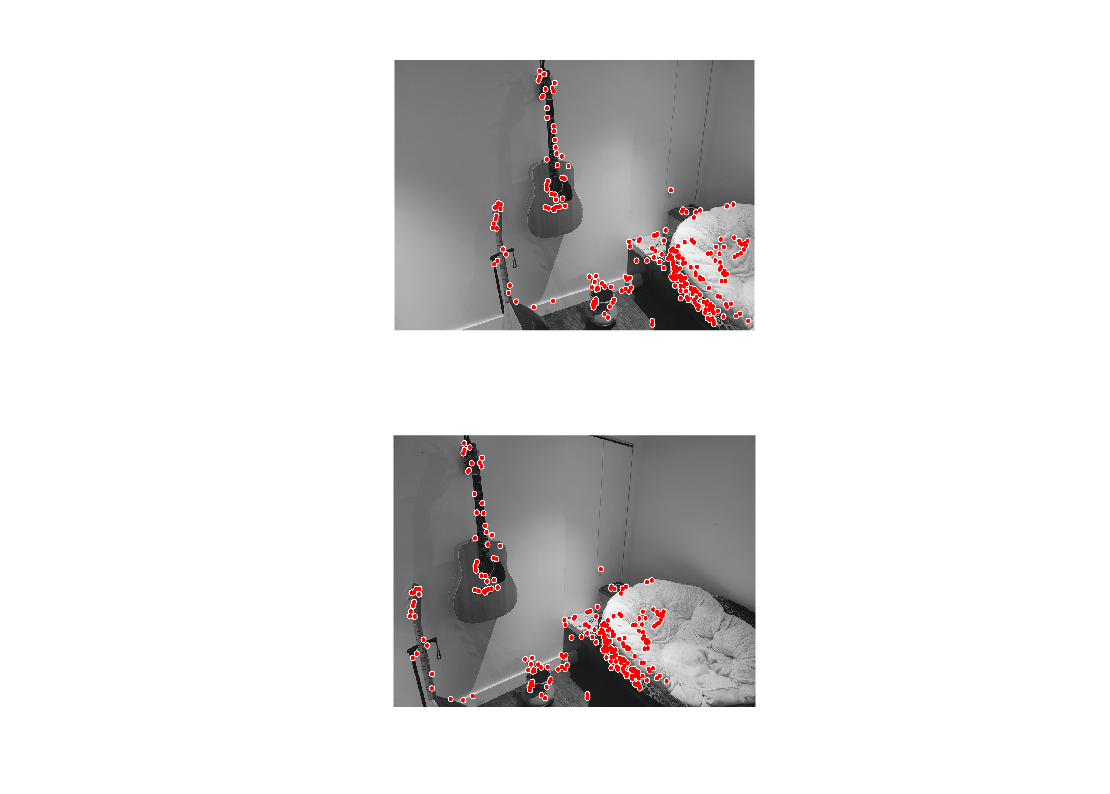


I1 = rgb2gray(I1);
I2 = rgb2gray(I2);

%returns a SIFTPoints object, points, containing information about SIFT features detected in the 2-D grayscale input image I. 
ptsLeft  = detectSIFTFeatures(I1); 
ptsRight = detectSIFTFeatures(I2);

%ExtractFeatures: Returns [features, validPoints], extracted feature vectors, also known as
%descriptors, and their corresponding locations.
[featuresLeft,  validPtsLeft]  = extractFeatures(I1,  ptsLeft);
[featuresRight, validPtsRight] = extractFeatures(I2, ptsRight);

%indexPairs the matching feature vectors and return the matching points
%index in featuresLeft, and featuresRight
indexPairs = matchFeatures(featuresLeft, featuresRight);

%Get the valid points using the index.
matchedLeft  = validPtsLeft(indexPairs(:,1));
matchedRight = validPtsRight(indexPairs(:,2));

% display matched attributes
clf reset;
subplot(2, 1, 1)
imshow(I1)
hold on
viscircles(matchedLeft.Location, 1*ones([1 length(matchedLeft.Location)]));
hold off
subplot(2,1,2)
imshow(I2)
hold on
viscircles(matchedRight.Location, 1*ones([1 length(matchedLeft.Location)]));
hold off

N = 100; % number of iterations for RANSAC
distance_threshold = 10; % what is considered a good distance between points

% step 1: already obtained features from part 1)

% step 2: randomly sample 4 pairs of feature points from both images
features_count = matchedLeft.Count;

best_consesus_set_size = 0;
best_homography = zeros([3 3]);

for k=1:N
    random_index_1 = randi([1 features_count], 1, 1);
    random_index_2 = randi([1 features_count], 1, 1);
    random_index_3 = randi([1 features_count], 1, 1);
    random_index_4 = randi([1 features_count], 1, 1);
    % fetch corresponding (xi,yi) and (xi',yi')
    x1 = floor(matchedLeft.Location(random_index_1, 1));
    x2 = floor(matchedLeft.Location(random_index_2, 1));
    x3 = floor(matchedLeft.Location(random_index_3, 1));
    x4 = floor(matchedLeft.Location(random_index_4, 1));
    y1 = floor(matchedLeft.Location(random_index_1, 2));
    y2 = floor(matchedLeft.Location(random_index_2, 2));
    y3 = floor(matchedLeft.Location(random_index_3, 2));
    y4 = floor(matchedLeft.Location(random_index_4, 2));
    x1_prime = floor(matchedRight.Location(random_index_1, 1));
    x2_prime = floor(matchedRight.Location(random_index_2, 1));
    x3_prime = floor(matchedRight.Location(random_index_3, 1));
    x4_prime = floor(matchedRight.Location(random_index_4, 1));
    y1_prime = floor(matchedRight.Location(random_index_1, 2));
    y2_prime = floor(matchedRight.Location(random_index_2, 2));
    y3_prime = floor(matchedRight.Location(random_index_3, 2));
    y4_prime = floor(matchedRight.Location(random_index_4, 2));
    
    % set up A matrix
    A = zeros([8 9]);
    A(1,1) = x1;
    A(1,2) = y1;
    A(1,3) = 1;
    A(1,7) = -1*x1_prime*x1;
    A(1,8) = -1*x1_prime*y1;
    A(1,9) = -1*x1_prime;
    
    A(2,4) = x1;
    A(2,5) = y1;
    A(2,6) = 1;
    A(2,7) = -1*y1_prime*x1;
    A(2,8) = -1*y1_prime*y1;
    A(2,9) = -1*y1_prime;
    
    A(3,1) = x2;
    A(3,2) = y2;
    A(3,3) = 1;
    A(3,7) = -1*x2_prime*x2;
    A(3,8) = -1*x2_prime*y2;
    A(3,9) = -1*x2_prime;
    
    A(4,4) = x2;
    A(4,5) = y2;
    A(4,6) = 1;
    A(4,7) = -1*y2_prime*x2;
    A(4,8) = -1*y2_prime*y2;
    A(4,9) = -1*y2_prime;
    
    A(5,1) = x3;
    A(5,2) = y3;
    A(5,3) = 1;
    A(5,7) = -1*x3_prime*x3;
    A(5,8) = -1*x3_prime*y3;
    A(5,9) = -1*x3_prime;
    
    A(6,4) = x3;
    A(6,5) = y3;
    A(6,6) = 1;
    A(6,7) = -1*y3_prime*x3;
    A(6,8) = -1*y3_prime*y3;
    A(6,9) = -1*y3_prime;
    
    A(7,1) = x4;
    A(7,2) = y4;
    A(7,3) = 1;
    A(7,7) = -1*x4_prime*x4;
    A(7,8) = -1*x4_prime*y4;
    A(7,9) = -1*x4_prime;
    
    A(8,4) = x4;
    A(8,5) = y4;
    A(8,6) = 1;
    A(8,7) = -1*y4_prime*x4;
    A(8,8) = -1*y4_prime*y4;
    A(8,9) = -1*y4_prime;
    
    % obtain SVD decomposition of A
    [U, S, V] = svd(A);
    % find column vector of V corresponding to a singular value of 0
    column_number = -1;
    for i=1:8
        if floor(S(i,i)) == 0
            column_number = i;
            break;
        end
    end
    
    if column_number == -1
        continue
    end

    % retrieve the H vector
    H_vector = V(:, column_number);
    % form the H matrix
    H = zeros([3 3]);
    H(1,1) = H_vector(1,1);
    H(1,2) = H_vector(2,1);
    H(1,3) = H_vector(3,1);
    H(2,1) = H_vector(4,1);
    H(2,2) = H_vector(5,1);
    H(2,3) = H_vector(6,1);
    H(3,1) = H_vector(7,1);
    H(3,2) = H_vector(8,1);
    H(3,3) = H_vector(9,1);
    % get feature locations obtained by applying the homography on the
    % feature locations of the left image, and see if they are close enough to
    % (xi',yi')
    current_consensus_set_size = 0;
    
    for i=1:features_count
        x_current_left = floor(matchedLeft.Location(i, 1));
        y_current_left = floor(matchedLeft.Location(i, 2));
    
        % retrieve true matches from right image
        x_true_right = floor(matchedRight.Location(i, 1));
        y_true_right = floor(matchedRight.Location(i, 2));
    
        % compute result of homography on matches in left image
        vector = H * [x_current_left; y_current_left; 1];
        vector = round(vector / vector(3, 1)); % divide by w and round
        x_hat = vector(1,1);
        y_hat = vector(2,1);
    
        % compute distance between true matches and matches under the
        % homography
        distance = sqrt((x_true_right - x_hat)^2 + (y_true_right - y_hat)^2);
        if distance < distance_threshold
            current_consensus_set_size = current_consensus_set_size + 1;
        end
    
    end
    
    % update best homography model
    if current_consensus_set_size >= best_consesus_set_size
        best_consesus_set_size = current_consensus_set_size;
        best_homography = H;
    end

end

best_homography

best_homography =    -0.0040   -0.0000    0.9709
   -0.0005   -0.0034    0.2395
   -0.0000    0.0000   -0.0026


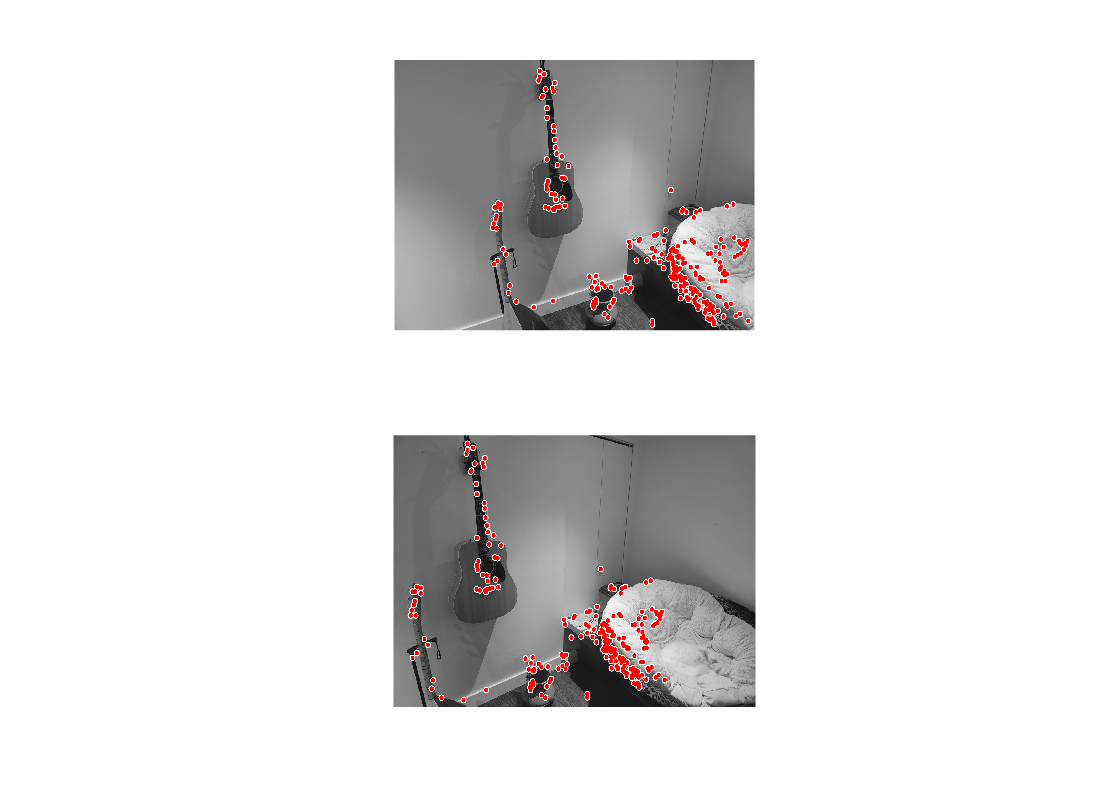


matched_locations = zeros([features_count 2]);

for i=1:features_count
    x_current_left = floor(matchedLeft.Location(i, 1));
    y_current_left = floor(matchedLeft.Location(i, 2));
    vector = best_homography * [x_current_left; y_current_left; 1];
    vector = round(vector / vector(3, 1)); % divide by w and round
    x_hat = vector(1,1);
    y_hat = vector(2,1);
    
    matched_locations(i, :) = [x_hat y_hat];
    
    
end

% display matched attributes
clf reset;
subplot(2, 1, 1)
imshow(I1)
hold on
viscircles(matchedLeft.Location, 1*ones([1 length(matchedLeft.Location)]));
hold off
subplot(2,1,2)
imshow(I2)
hold on
viscircles(matched_locations, 1*ones([1 length(matched_locations)]));
hold off

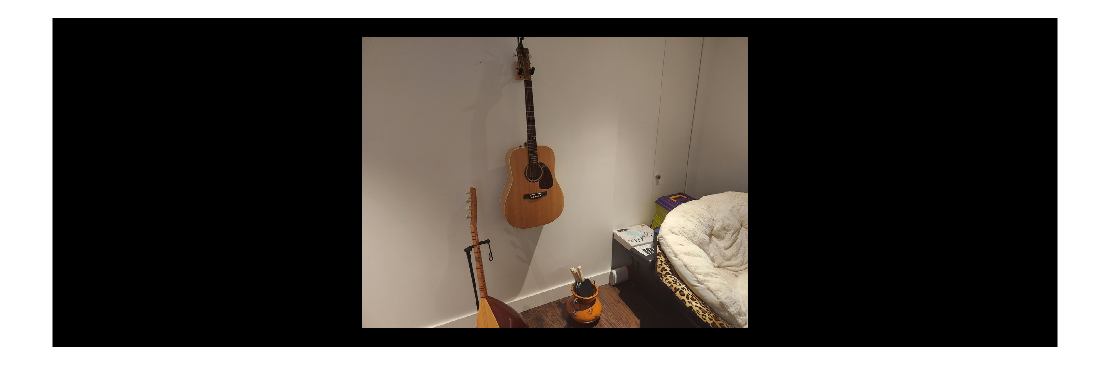

[height, width] = size(I1);
original_I1 = imread("q3_part5_img1.jpg");
original_I2 = imread("q3_part5_img2.jpg");
canvas = padarray(original_I1, [50 800], 'both');

clf reset;
imshow(canvas)

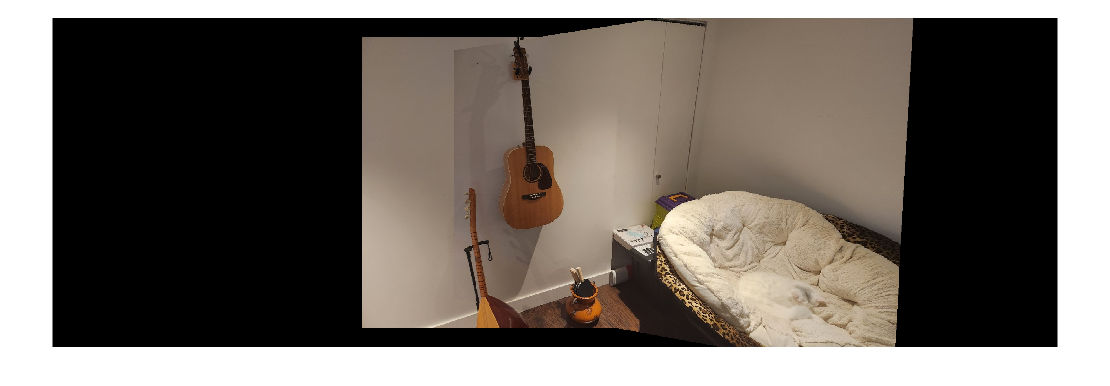

[canvas_height, canvas_width] = size(canvas);

for x=1:canvas_width
    for y=1:canvas_height
        
        % the origin corresponds to the top-left of the original image
        % therefore x will be x - 800
        % and y will be y - 50 (these are the padding sizes)
        x_canvas = x - 800;
        y_canvas = y - 50;

        % get location in right image through homography
        vector = best_homography * [x_canvas; y_canvas; 1];
        vector = round(vector / vector(3, 1)); % divide by w and round
        x_hat = vector(1,1);
        y_hat = vector(2,1);

        % get RGB only if it's a valid pixel
        if x_hat >= 1 && x_hat <= width && y_hat >= 1 && y_hat <= height
            pixel = original_I2(y_hat, x_hat, :);
            % color corresponding slot
            canvas(y, x, :) = pixel;
        end
        
    end
end

clf reset;
imshow(canvas)